clc;clear;close all;
quanser_aero_parameters
quanser_aero_state_space
s = tf('s');
G = ss(A,B,C,D)


G =
 
  A = 
            x1       x2       x3       x4
   x1        0        0        1        0
   x2        0        0        0        1
   x3   -1.712        0  -0.3249        0
   x4        0        0        0       -1
 
  B = 
            u1       u2
   x1        0        0
   x2        0        0
   x3  0.05026  0.09595
   x4  -0.1228      0.1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



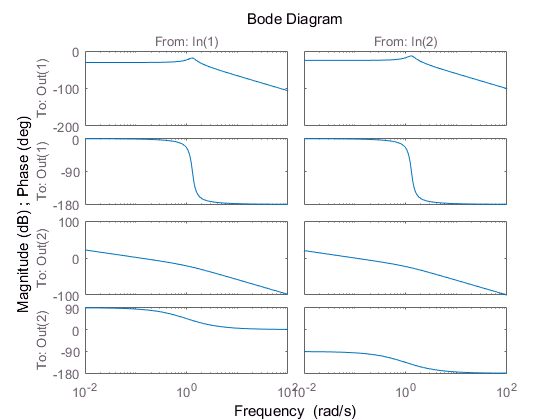

Ld = 5/s;
bode(G)

**SISO:**

For G(1,1):

G1 = tf(G(1,1));
G1_inv_improper = inv(G1);
G1_inv = G1_inv_improper * 1/(s/1000 + 1)^2;
K1  = minreal(G1_inv * Ld)


K1 =
 
  9.949e07 s^2 + 3.233e07 s + 1.703e08
  ------------------------------------
        s^3 + 2000 s^2 + 1e06 s
 
Continuous-time transfer function.



For G(2,2):

G2 = tf(G(2,2));
G2_inv_improper = inv(G2);
G2_inv = G2_inv_improper * 1/(s/1000 + 1)^2;
K2  = minreal(G2_inv * Ld)


K2 =
 
   4.998e07 s + 5e07
  -------------------
  s^2 + 2000 s + 1e06
 
Continuous-time transfer function.



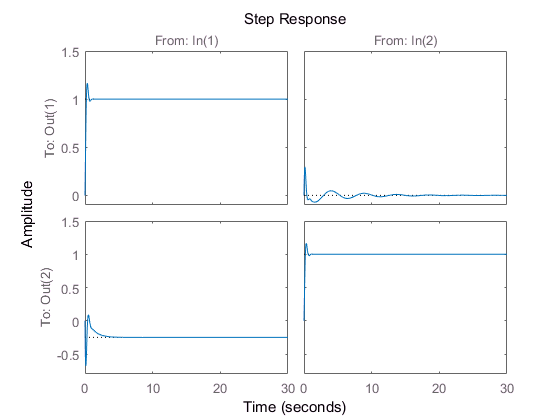

K_loop_siso = [K1 0;0 K2];
L = G * K_loop_siso;
S = inv(eye(2) + L);
T = eye(2) - S;
step(T)

**DIDO:**

Ld_dido = [Ld 0; 0 Ld];
G_total = tf(G);
G_inv_improper = inv(G_total);
G_inv = G_inv_improper * 1/(s/1000 + 1)^2;
K_loop_dido = minreal(G_inv * Ld_dido)


K_loop_dido =
 
  From input 1 to output...
       2.976e07 s^2 + 9.67e06 s + 5.094e07
   1:  -----------------------------------
             s^3 + 2000 s^2 + 1e06 s
 
       3.652e07 s^2 + 1.187e07 s + 6.252e07
   2:  ------------------------------------
             s^3 + 2000 s^2 + 1e06 s
 
  From input 2 to output...
       -2.854e07 s - 2.855e07
   1:  ----------------------
        s^2 + 2000 s + 1e06
 
       1.495e07 s + 1.496e07
   2:  ---------------------
        s^2 + 2000 s + 1e06
 
Continuous-time transfer function.



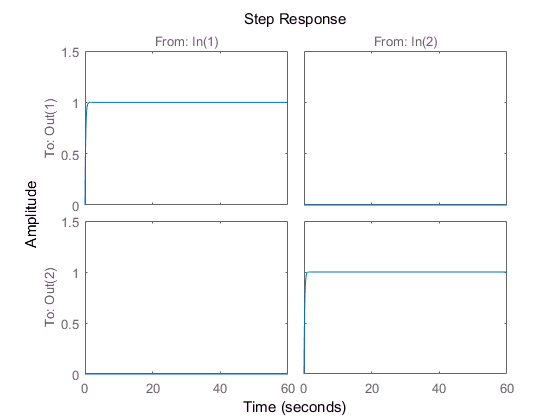

L = G_total * K_loop_dido;
S = inv(eye(2) + L);
T = eye(2) - S;
step(T)